# AirQuant tutorial: Airways in clinical chest CT 

By Ashkan Pakzad, 2022. ashkanpakzad.github.io

Configure case dataset files from AirQuant's example clinical chest scan.

(add info on scan)

%% Add AirQuant to path
AirQuantDir = AirQuantAddPath();
% set dataset and casename
dataset = 'airquant';
casename = 'chestct';

% set up results directory
results_dir = fullfile(AirQuantDir,'results', dataset, casename);

% get CT, segmentation and skeleton images of the case
CT_name = [casename, '_source.nii.gz'];
seg_name = [casename, '_airway.nii.gz'];
skel_name = [casename, '_airway_PTKskel.nii.gz'];

Load data into relevant formations from nifti images.

% Load the source CT metadata information
meta = niftiinfo(CT_name);
% Load CT data as double
source = double(niftiread(meta));

% Load Airway segmentation and its skeleton as logicals
seg = logical(niftiread(seg_name));
skel = logical(niftiread(skel_name));

## Make AirQuant object

There are lots of options here, be sure to check the documentation.

This is the major step where the airway tree is broken down into its constituent branches. Splines are fitted to each branch, making the backbone of our analysis.

AQnet = ClinicalAirways(source, meta, seg, skel, fillholes=1, largestCC=1, plane_sample_sz=0.5, spline_sample_sz=0.5);

Voxel dimensions (in physical units, usually mm) = 0.63672     0.63672         0.5
Patch sampling size (in physical units, usually mm) = 0.5
Spline sampling size (in physical units, usually mm) = 0.5
Max plane size (in physical units, usually mm) = 40
142 tubes found.
RunAllTubes:SetGener:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]
RunAllTubes:ComputeD:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]
RunAllTubes:ComputeC:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]
RunAllTubes:ComputeP:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]
RunAllTubes:ComputeS:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]
RunAllTubes:SetGener:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]


% note: if you are running this in a live matlab script then the progress bar
% will not function properly.

Visualisation of data to give you an idea.

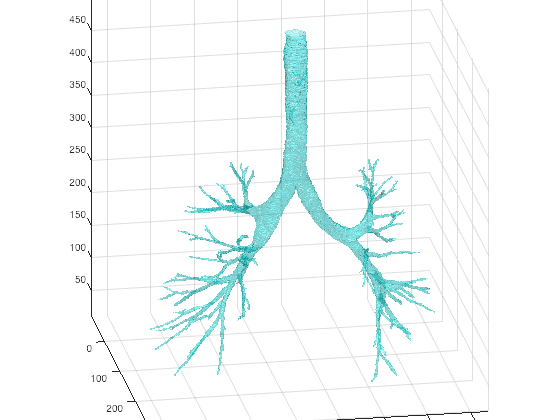

figure;
AQnet.Plot3D();

There are **lots** of visualisation options. Here we go for the graph visualisations.

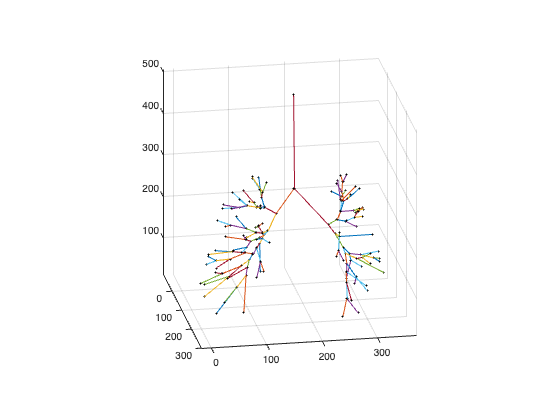

figure;
AQnet.Plot3();

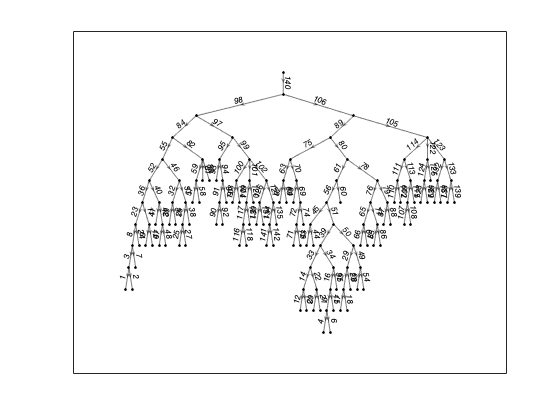

figure;
AQnet.Plot();

% note that the edge labels correspond to the segment indicies

`ClinicalAirways` class has its own method for implementing **automated lobe classification**. We can call this to run on the image.

The `colour` option can also be called for any visualisation method. Here it is called to show the lobes

AQnet.ClassifyLungLobes();

% We can use lobe region classifications to further enrich our visualisation.
figure; AQnet.Plot3D(colour='lobe');

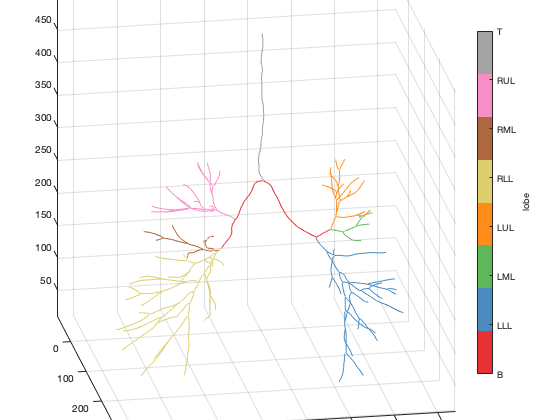

% this function can take a while depending on your specs. You may want to
% skip it.
figure; AQnet.PlotSpline(colour='lobe');

Now that the backbone of the AirQuant analysis has been set up, we can work through subsequent steps of interpolating the source image for airway measurement. 

% we opt to only demonstrate this on one airway, though in reality we want
% this to be done on every airway. We pick one airway id.
tubeid = 99;

% we can access any 'tube' (airway) by its index, this allows us to access
% the methods of tubes.
tube99 = AQnet.tubes(99);

% We run the method make the airway patch slices of this airway on the CT.
usegpu = 0;
tube99.MakePatchSlices(AQnet.source, type='source', method='linear', gpu=usegpu);
% if this fails for you, change usegpu to 0.

We can **interactively** visualise the CT image along the airway patches with its estimated **ellipse** fitting.

figure; tube99.OrthoView();

ans =   orthosliceViewer with properties:

               SliceNumbers: [41 41 11]
             CrosshairColor: [1 1 0]
         CrosshairLineWidth: 0.3000
       CrosshairStripeColor: 'none'
            CrosshairEnable: 'on'
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [-1024 560.9071]
               ScaleFactors: [0.5000 0.5000 0.5000]
    DisplayRangeInteraction: 'off'


% (opens externally)

With our airway patches interpolated we now run the measurement of each patch. We use the most straightforward, FWHMesl.

%% set up parameters of FWHMesl
num_rays = 60;
ray_interval = 0.2;
% segmentation interpolation is required for the FWHMesl method
tube99.MakePatchSlices(AQnet.seg, type='seg', method='linear', gpu=usegpu);
tube99.Measure('AirwayFWHMesl', num_rays, ray_interval);
% rerun orthoview to view patches with measurements
figure; tube99.OrthoView();

We can plot any measurement along the airway against its arc-length

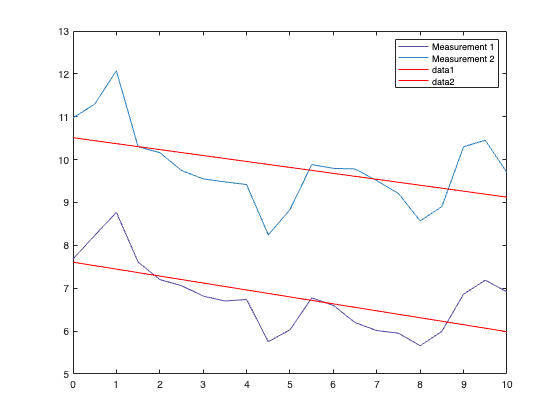

figure; tube99.plot(Y='diameters');

% though this is the default options for X and Y, we will be explicit.

We can go ahead and process all airways now. This can take somewhere between 1-4 hours to run. By default it will try to run on GPU if available.

%% process all airways to make patches
AQnet.MakeTubePatches(method='linear', gpu=usegpu)

Making tube patches:  000%  |                                      | 0/142it [00:00:00<Inf:NaN:NaN, Inf it/s]


%% process FWHMesl measurement
AQnet.Measure('AirwayFWHMesl', num_rays, ray_interval);

We can now visualise the characteristics derived from diameter measurements.

figure; AQnet.Plot(colour='lobe', weight='meandiameter', weightfactor='10')

We can export all variables of the `TubeNetwork`.

AQnet.ExportCSV('tutorial.csv');

Or of individual tubes/airways.

tube99.ExportCSV('tutorial_99.csv');